# Изучение красного смещения звезд

close all
clear variables

### **Импорт данных**

spectra = importdata('spectra.csv')

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


lambdaStart = importdata('lambda_start.csv')

lambdaStart = 630.0200

lambdaDelta = importdata('lambda_delta.csv')

lambdaDelta = 0.1400

### Определение диапазона длин волн

nObs = size(spectra, 1)  % number(n) of observations

nObs = 357

nSt = size(starNames, 1)  % n of stars

nSt = 7


lambdaEnd = lambdaStart + (nObs-1) * lambdaDelta 

lambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta : lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


### **Константы**

lambdaPr = 656.28; %nanomet
speedOfLight = 299792.458; %km/s

### **Расчет скорости удаления звезд от Земли**

[sHa, idx] = min(spectra)

sHa = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


idx =    188   187   188   189   189   191   185


lambdaHa = lambda(idx)

lambdaHa =   656.2000
  656.0600
  656.2000
  656.3400
  656.3400
  656.6200
  655.7800



z = (lambdaHa / lambdaPr) - 1

z = 	1.0e+-3 *

   -0.1219
   -0.3352
   -0.1219
    0.0914
    0.0914
    0.5181
   -0.7619


speed = z * speedOfLight

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


movaway = starNames(speed > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


### **График**

fig = figure

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [361 279 560 420]
       Units: 'pixels'

  Show all properties



plt = plot(lambda, spectra, '--', 'LineWidth', 1)

plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line



for i = 1 : 1 : nSt
    if speed(i) > 0
        plt(i).LineWidth = 3
        plt(i).LineStyle = '-'
    end
end

plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line


plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line


plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line


plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line


plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line


plt =   7×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line



set(fig, 'Visible', 'on')

xlabel('Длина волны, нм')
ylabel(['Интенсивность эрг/см^2/с/', char(197)])
title('Спектры звёзд')
legend(starNames, 'Location', 'Northeast')
grid on
text(lambdaEnd - 45, max(spectra(1))*0.8, 'Михаил Голощапов Б04-005')

### Сохранить график

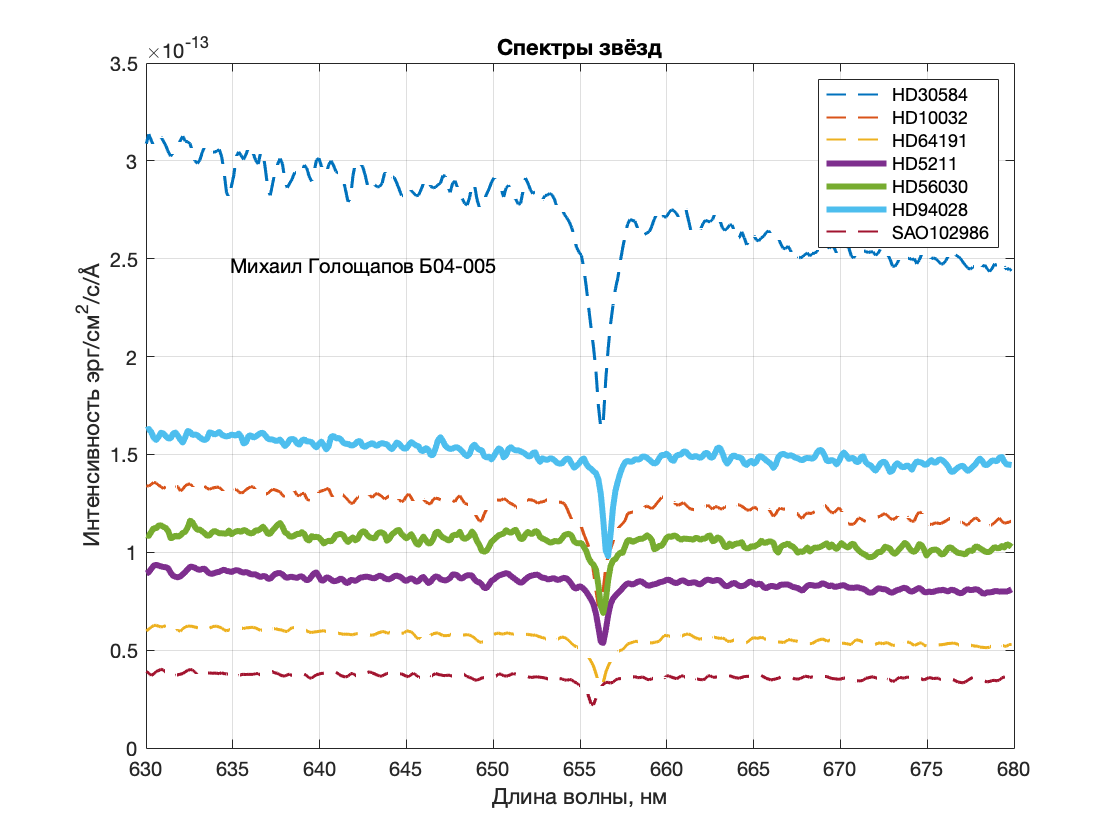

saveas(fig, 'spectraAll', 'png')